clc
clear
close all

% 3关节平面转动机器人
% theta         d              a           alpha
theta1 = 0.0;   d1 = 0.0;      a1 = 1.0;   alpha1 = 0;
theta2 = 0.0;   d2 = 0.0;      a2 = 1.0;   alpha2 = 0;
theta3 = 0.0;   d3 = 0.0;      a3 = 1.0;   alpha3 = 0;

Lr1 = Link('d', d1, 'a', a1, 'alpha', alpha1, 'revolute','offset', theta1);
Lr2 = Link('d', d2, 'a', a2, 'alpha', alpha2, 'revolute','offset', theta2);
Lr3 = Link('d', d3, 'a', a3, 'alpha', alpha3, 'revolute','offset', theta3);
robot = SerialLink([Lr1 Lr2 Lr3], 'name', 'RRR\_bot')

 
robot = 
 
RRR\_bot:: 3 axis, RRR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
|  3|         q3|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


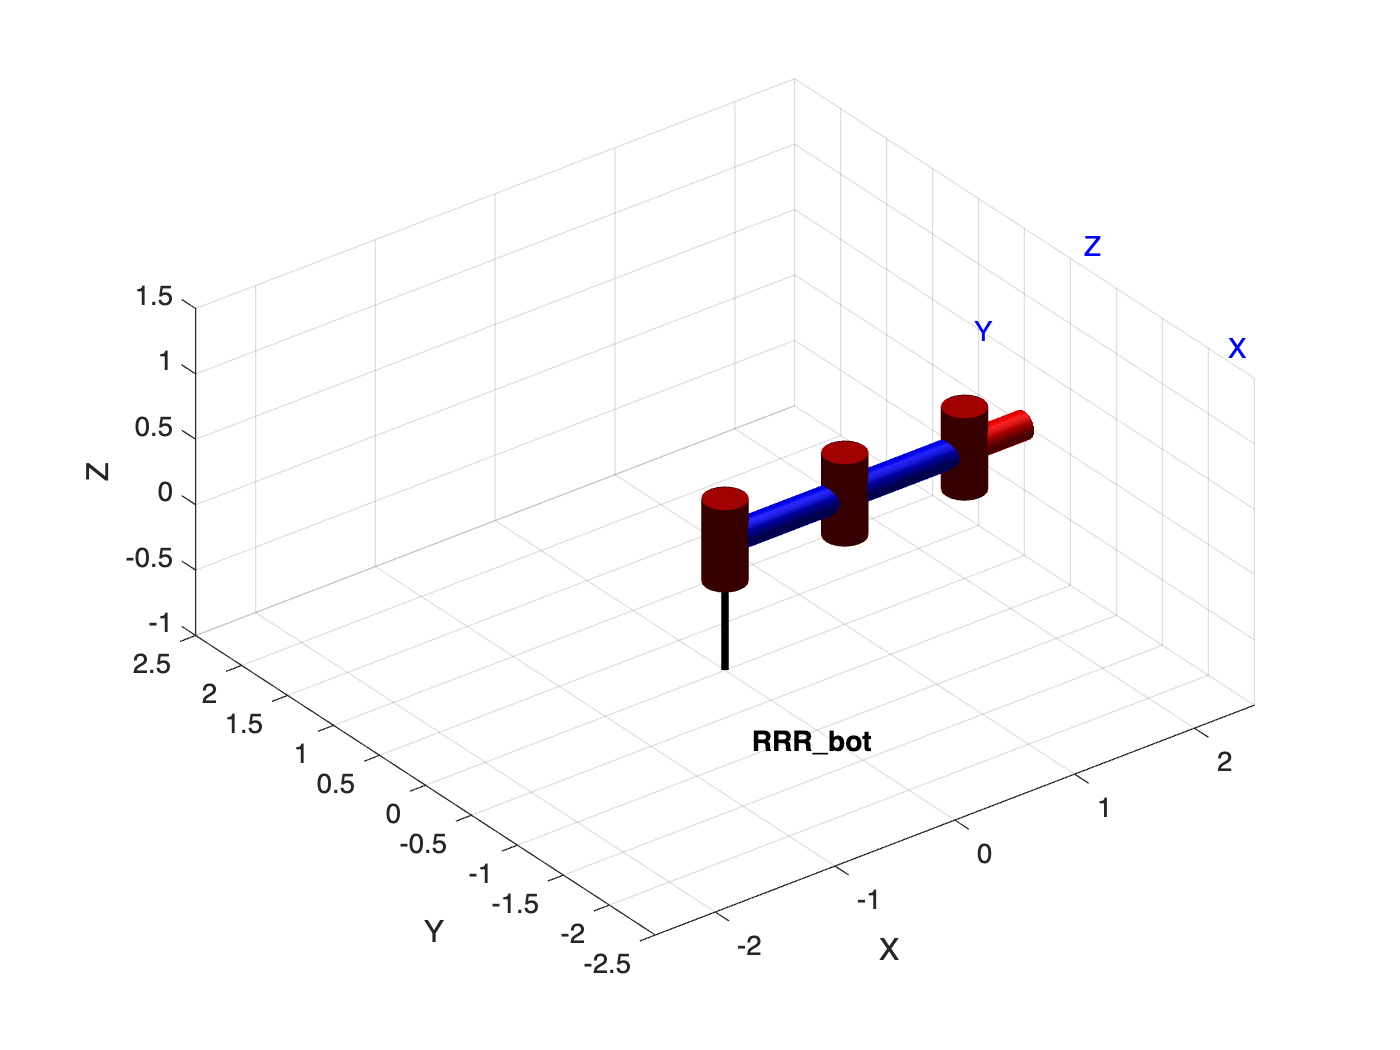


% 指定初始关节变量
q1 = 0; q1 = q1*pi/180;     % 第一个回转关节的回转角度
q2 = 0; q2 = q2*pi/180;     % 第二个回转关节的回转角度
q3 = 0; q3 = q3*pi/180;     % 第三个回转关节的回转角度
q = [q1, q2, q3];

% 显示机器人，并看到关节的构型
view([45.0 45.0]); 
plotvol([-2.50 2.5 -2.5 2.5 -1.0 1.5]);
robot.plot(q);

% 在该例子中是平面机械臂，因此末端只有x,y的平动和沿z轴的转动\theta
% 定义平动目标和转动角度
x = 2.5;
y = 0.5;
theta = 30; theta = theta*pi/180; 

% 根据目标得到齐次变换矩阵Td（H）
Td = [cos(theta), -sin(theta), 0, x ;
      sin(theta),  cos(theta), 0, y ;
      0         ,  0         , 1, 0 ;
      0         ,  0         , 0, 1 ]

Td =     0.8660   -0.5000         0    2.5000
    0.5000    0.8660         0    0.5000
         0         0    1.0000         0
         0         0         0    1.0000



% 调用Robot Toolbox计算逆运动学, mask表明只有x,y平动和z转动
qd0 = robot.ikine(Td,'mask', [1; 1; 0; 0; 0; 1], 'verbose', true)

10 iterations


qd0 =    -0.6146    1.2293   -0.0910


% 近似方法求解姿态误差到末端速度的映射

% 步骤1：设初始关节为迭代起点
k = 0;
qk = q'; % -> 列向量

while true
    % 步骤2：根据正运动学计算估计值对应的姿态矩阵
    Te = robot.fkine(qk);  
    Tk = Te.T; % SE3 -> 4*4 matrix

    % 步骤3：计算当前估计位姿与目标位姿的偏差
    Delta = Tk\(Td - Tk); 

    % 将误差转化为末端坐标系中的速度
    v = Delta(1:3,4);     
    omega = [-Delta(2,3); Delta(1,3); -Delta(1,2)];
    Vb = [v ; omega];

    % 步骤4：判断平动和转动速度是否小于设定阈值，是则迭代终止
    if (norm(v) <= 1e-3) && (norm(omega) <= 1e-3)
        break;              
    end
    %       或者为了保证算法结束，达到最大迭代次数后终止
    if k > 100
        break;
    end

    % 步骤5：根据速度和末端Jacobian求解关节变化量dq
    Jk = robot.jacobe(qk);  % 得到Jacobian在末端坐标系中的表达
    dq = pinv(Jk)*Vb;
    
    % 步骤6: 迭代关节量，回到第2步
    qk = qk+dq;
    k = k+1;
    
    % 展示迭代第k次对应的qk
%     k
%     disp(qk')

end

k % 迭代次数

k = 6

qd1 = qk' % 迭代终值

qd1 =    -0.6146    1.2293   -0.0910



% 用Fkine求迭代结束位置的变换矩阵，与期望的姿态进行比较
T = robot.fkine(qk)

 

T = 
    0.8660   -0.5000         0       2.5
    0.5000    0.8660         0       0.5
         0         0         1         0
         0         0         0         1


Td

Td =     0.8660   -0.5000         0    2.5000
    0.5000    0.8660         0    0.5000
         0         0    1.0000         0
         0         0         0    1.0000


% 精确求解姿态误差到末端速度的映射，理论上能比近似求解有更快的迭代速度
% 其和近似方法的区别在第3步

% 步骤1：设初始关节为迭代起点
k = 0;
qk = q'; % -> 列向量

while true
    % 步骤2：根据正运动学计算估计值对应的姿态矩阵
    Te = robot.fkine(qk);  
    Tk = Te.T; % SE3 -> 4*4 matrix

    % 步骤3：计算当前估计位姿与目标位姿的偏差
    DeltaT = Tk\Td; 

    % 将误差转化为末端坐标系中的速度
    screwV = SE3(DeltaT).log();
    v = screwV(1:3,4);     
    omega = [-screwV(2,3); screwV(1,3); -screwV(1,2)];
    Vb = [v ; omega];

    % 步骤4：判断平动和转动速度是否小于设定阈值，是则迭代终止
    if (norm(v) <= 1e-3) && (norm(omega) <= 1e-3)
        break;              
    end

    % 或者为了保证算法结束，达到最大迭代次数后终止
    if k > 100
        break;
    end

    % 步骤5：根据速度和末端Jacobian求解关节变化量dq
    Jk = robot.jacobe(qk);  % 得到Jacobian在末端坐标系中的表达
    dq = pinv(Jk)*Vb;

    % 步骤6: 迭代关节量，回到第2步
    qk = qk+dq;
    k = k+1;
    
    % 展示迭代第k次对应的qk
%     k
%     disp(qk')
end

k % 迭代次数

k = 5

qd2 = qk' % 迭代终值

qd2 =    -0.6147    1.2294   -0.0911


% 用Fkine求迭代结束位置的变换矩阵，与期望的姿态进行比较
T = robot.fkine(qk)

 

T = 
    0.8660   -0.5000         0       2.5
    0.5000    0.8660         0       0.5
         0         0         1         0
         0         0         0         1


Td

Td =     0.8660   -0.5000         0    2.5000
    0.5000    0.8660         0    0.5000
         0         0    1.0000         0
         0         0         0    1.0000
